%Load Data
data = chickenpox_dataset;
data = [data{:}];

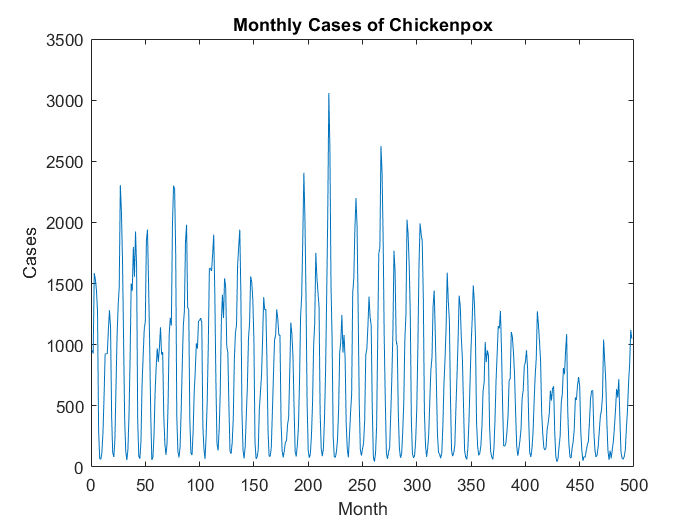

%Plot Data
figure
plot(data)
xlabel("Month")
ylabel("Cases")
title("Monthly Cases of Chickenpox")

%Partition Data
numTimeStepsTrain = floor(0.9*numel(data));
dataTrain = data(1:numTimeStepsTrain+1);
dataTest = data(numTimeStepsTrain+1:end);

%Normalize data
mu = mean(dataTrain);
sig = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sig;

% Prepare Predictors and Response variables
% The values will be shifted by one time step. Shifted value will be the
% reponse variable
XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

% Create LSTM Network Architecture
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 200;
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
options = trainingOptions('adam', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

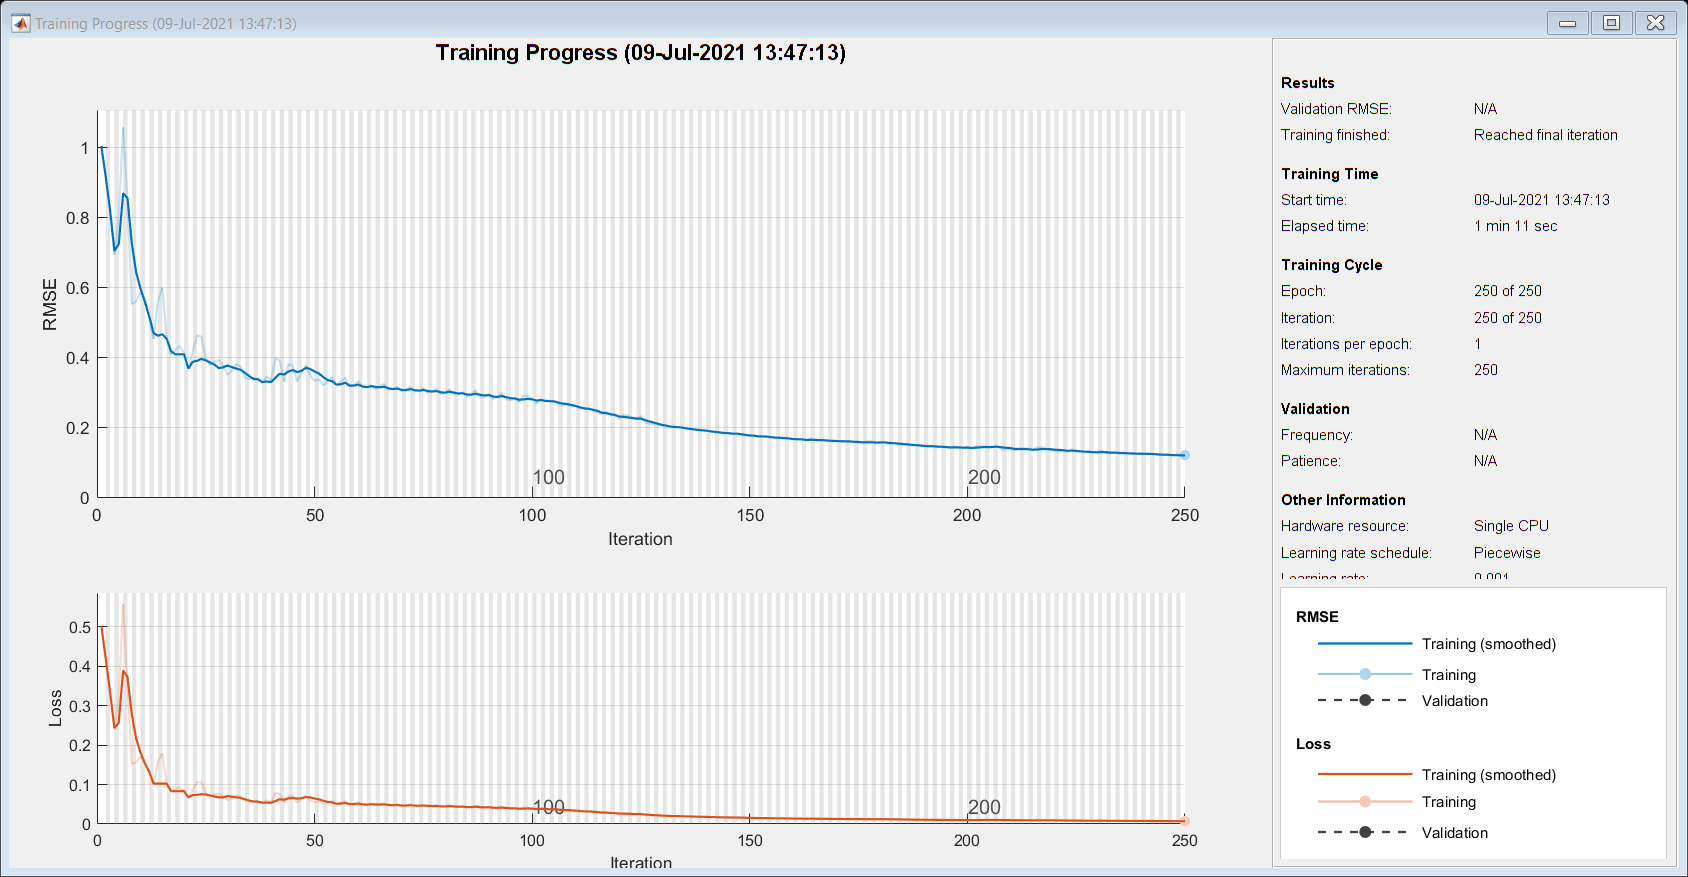

%Run the LSTM Network
net = trainNetwork(XTrain,YTrain,layers,options);

% 1. Forecast Multiple time steps. In this case one step at a time is
% predicted and network state at each stage is updated
% 2. For each prediction, the previous prediction is used as input
% 3. Test data is standardized similar to the Train data
dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);

% First predict on the training data XTrain. 
% Next, make the first prediction using the last time step of the training response YTrain(end). 
% Finally, use "predictAndUpdateState" function to predict time steps one at a time. Loop over the remaining predictions and input the previous prediction to predictAndUpdateState.
net = predictAndUpdateState(net,XTrain);
YTrain = dataTrainStandardized(2:end);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

% De-normalize/Unstandardize  the data
YPred = sig*YPred + mu;

% Calculate RMSE
YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))

rmse = single
219.0945

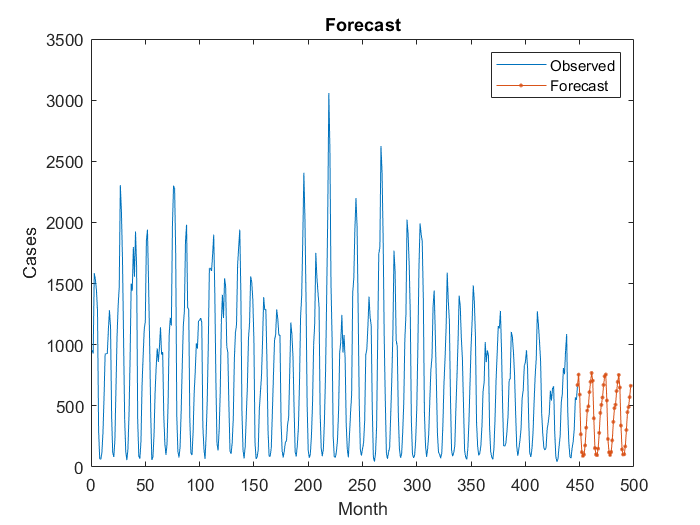

% Plot actual vs forecasted values
figure
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[data(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])

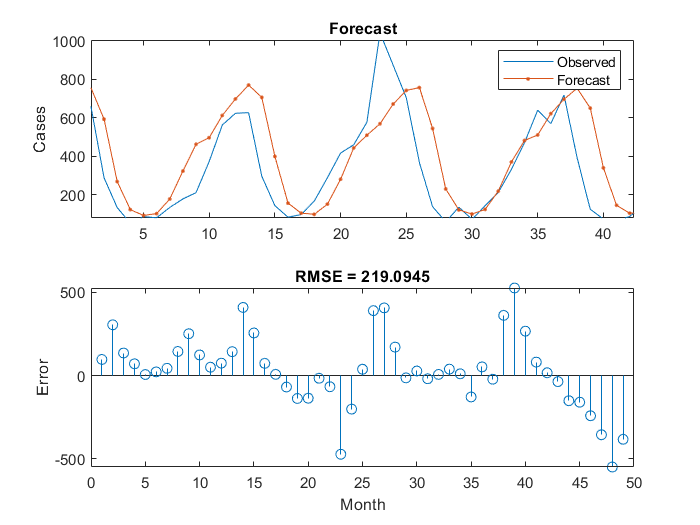

% Compare forecasted values with Test values
figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

% Update Network State with Observed Values
% If we have access to the actual values of time steps between predictions, 
% then we can update the network state with the observed values 
net = resetState(net);  
net = predictAndUpdateState(net,XTrain);

% Predict on each time step. For each prediction, predict the next time step using the observed value of the previous time step.
YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu; %De-normalize

rmse = sqrt(mean((YPred-YTest).^2))

rmse = 124.4591

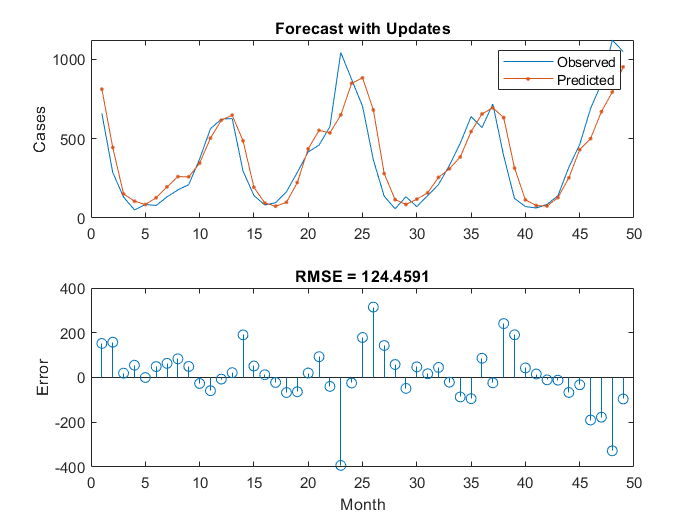

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Cases")
title("Forecast with Updates")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)